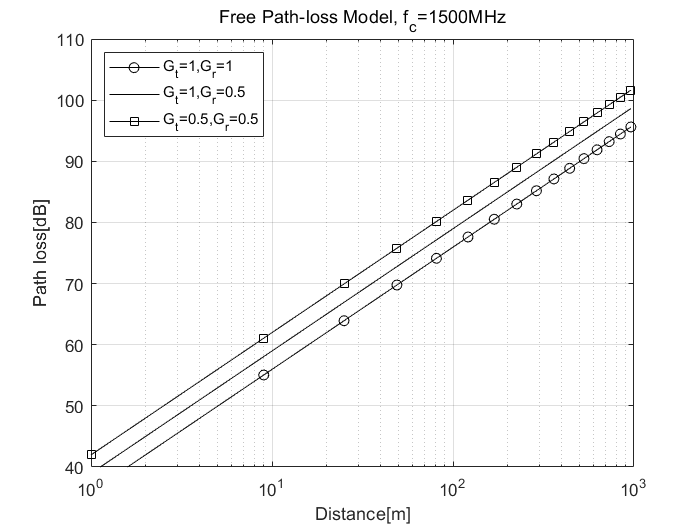

clear,clc
fc = 1.5e9;
d0 = 100;
sigma = 3;
distance = (1:2:31).^2;
Gt = [1 1 0.5];
Gr = [1 0.5 0.5];
u_n = [2 3 6]; %路径损耗指数
y_Free = zeros(3,length(distance));
y_logdist = zeros(3,length(distance));
y_lognorm = zeros(3,length(distance));
for k = 1:3
    y_Free(k,:)=PL_free(fc,distance,Gt(k),Gr(k));
    y_logdist(k,:)=PL_logdist_or_norm(fc,distance,d0,u_n(k));
    y_lognorm(k,:)=PL_logdist_or_norm(fc,distance,d0,u_n(1),sigma);
end
semilogx(distance,y_Free(1,:),'k-o',distance,y_Free(2,:),'k-',distance,y_Free(3,:),'k-s')
grid on,axis([1 1000 40 110])
title(['Free Path-loss Model, f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('G_t=1,G_r=1','G_t=1,G_r=0.5','G_t=0.5,G_r=0.5','Location','northwest')

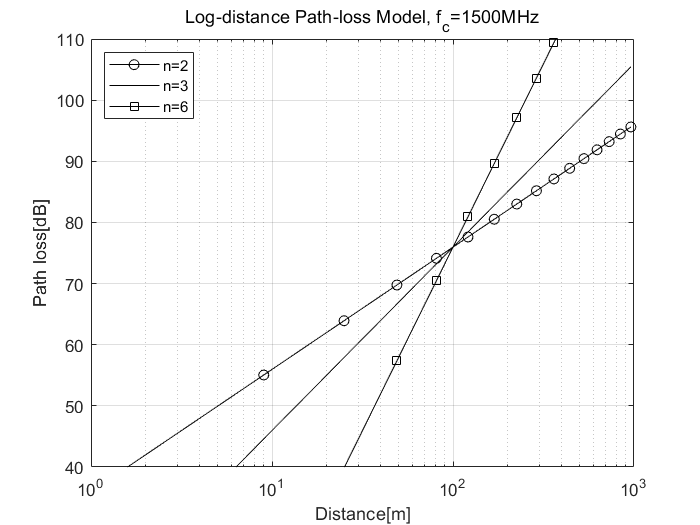

semilogx(distance,y_logdist(1,:),'k-o',distance,y_logdist(2,:),'k-',distance,y_logdist(3,:),'k-s')
grid on,axis([1 1000 40 110])
title(['Log-distance Path-loss Model, f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('n=2','n=3','n=6','Location','northwest')

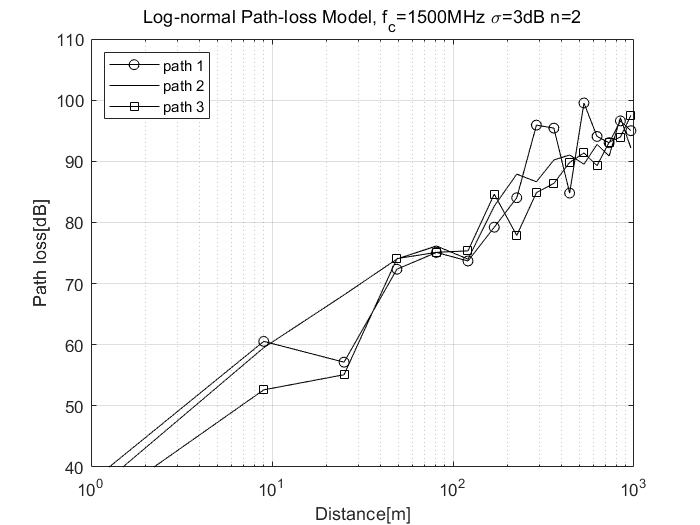

semilogx(distance,y_lognorm(1,:),'k-o',distance,y_lognorm(2,:),'k-',distance,y_lognorm(3,:),'k-s')
grid on,axis([1 1000 40 110])
title(['Log-normal Path-loss Model, f_c=',num2str(fc/1e6),'MHz',' \sigma=',num2str(sigma),'dB',' n=',num2str(u_n(1))])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('path 1','path 2','path 3','Location','northwest')